# Link to a Slide Using the Target Slide Index

This example links to a slide using an `mlreportgen.ppt.InternalLink` object that specifies the target slide number.

Create the presentation.

import mlreportgen.ppt.*
ppt = Presentation("myPresentation2.pptx");
open(ppt);

Add a slide to the presentation.

slide1 = add(ppt,"Title and Content");

 Create a paragraph. Create an `InternalLink` object that specifies the target slide by its index and append the object to the paragraph.

p = Paragraph("This is a link to ");
link = InternalLink(3,"slide 3");
append(p,link);

Add the title and content to the slide.

replace(slide1,"Title","First slide");
replace(slide1,"Content",p);

 Add a slide 2 to the presentation.

slide2 = add(ppt,"Title and Content");
replace(slide2,"Title","Second slide");

Add the target slide, slide 3, to the presentation.

slide3 = add(ppt,"Title and Content");
replace(slide3,"Title","Third slide");
replace(slide3,"Content","This is the target slide");

Close and view the presentation.

close(ppt);
rptview(ppt);

Here are the generated slides:

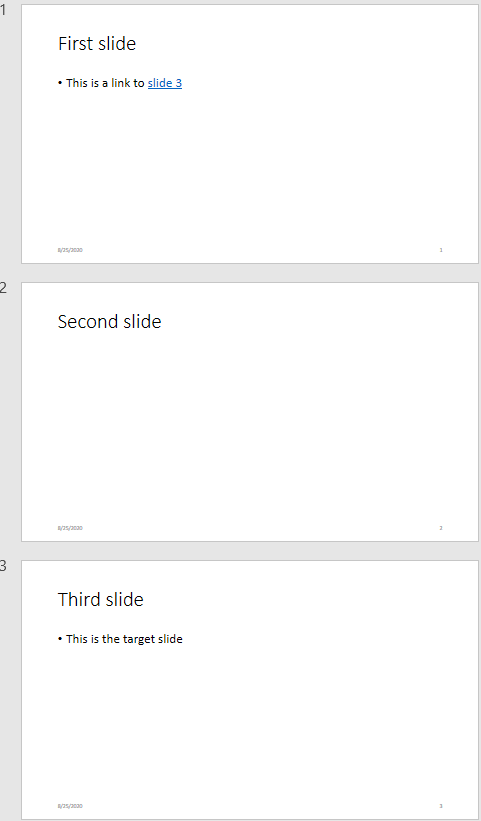

*Copyright 2020 The MathWorks, Inc.*